%rosshutdown
%init_turtlebot_connection('10.42.0.1', '10.42.0.157')

%rossub = rossubscriber('/tf');
%pause(1);
rospubRest = rospublisher("/mobile_base/commands/reset_odometry","Dataformat", "struct");
resetMsg = rosmessage(rospubRest);
send(rospubRest,resetMsg)

path = [0 0;
        0 2;
        2 2];
robotInitialLocation = path(1,:);

robotGoal = path(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]'; 

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

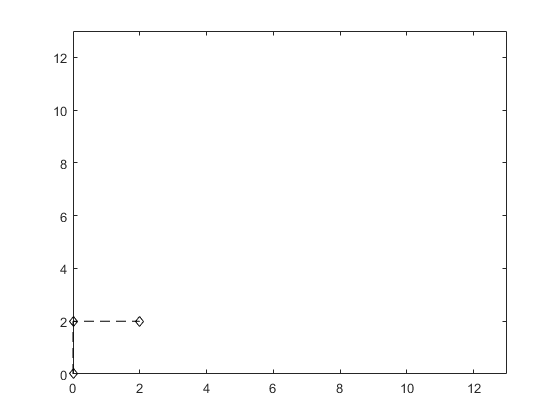

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 13])
ylim([0 13])

controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 2;
controller.MaxAngularVelocity = 2;
controller.LookaheadDistance = 0.2;
goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal)+1;

rospub = rospublisher("/mobile_base/commands/velocity","Dataformat", "struct");
rossub = rossubscriber("/tf");
velmsg = rosmessage(rospub);

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    velmsg.Linear.X = vel(1);
    velmsg.Angular.Z = vel(3);
    send(rospub, velmsg);
    
    % Update the current pose
    %robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    msg3 = receive(rossub,3);
    transform = msg3.Transforms.Transform;
    robotCurrentPose = [transform.Translation.X; transform.Translation.Y; transform.Rotation.Z];
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
%      % Update the plot
%     hold off
%     
%     % Plot path each instance so that it stays persistent while robot mesh
%     % moves
%     plot(path(:,1), path(:,2),"k--d")
%     hold all
%     
%     % Plot the path of the robot as a set of transforms
%     plotTrVec = [robotCurrentPose(1:2); 0];
%     plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
%     plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
%     light;
%     xlim([100 100])
%     ylim([100 100])
%    
    
    waitfor(vizRate);
end

Error using ros.Subscriber/receive (line 430)
The function did not receive any data and timed out.